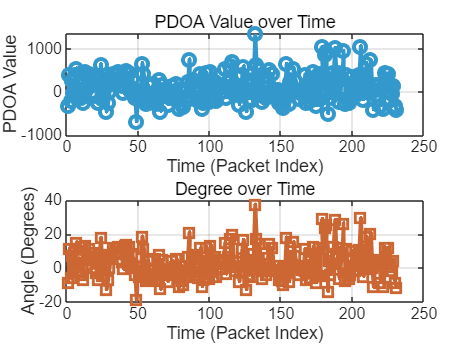

% 文件名
filename = '.\Data\Calibration\pdoa_2.txt';

% 打开文件
fid = fopen(filename, 'r');

% 初始化存储
pdoa_values = [];
degree_values = [];

% 逐行读取
while ~feof(fid)
    line = fgetl(fid);  % 读取一行
    
    % 使用正则表达式提取数值
    tokens = regexp(line, 'PDOA val = ([\-\d\.]+), Degrees = ([\-\d\.]+)', 'tokens');
    
    if ~isempty(tokens)
        % 提取值并转换为数字
        pdoa_val = str2double(tokens{1}{1});
        degree_val = str2double(tokens{1}{2});
        
        % 存入数组
        pdoa_values(end+1, 1) = pdoa_val;
        degree_values(end+1, 1) = degree_val;
    end
end

% 关闭文件
fclose(fid);
% pdoa_values = pdoa_values(10:end);
% degree_values = degree_values(10:end);
time = 1:length(pdoa_values);
figure;

subplot(2,1,1);
plot(time, pdoa_values, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, degree_values, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;




% 1. 计算平均值
mean_pdoa = mean(pdoa_values);
mean_degree = mean(degree_values);

% 2. 计算标准差
std_pdoa = std(pdoa_values);
std_degree = std(degree_values);

% 3. 最大值和最小值
max_pdoa = max(pdoa_values);
min_pdoa = min(pdoa_values);

max_degree = max(degree_values);
min_degree = min(degree_values);


% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: 101.39


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 322.47



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: 2.84


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 9.02


% 输入两条直角边
a = 1.74;  % 较短的边
b = 2.345;  % 较长的边

% 计算斜边（仅供理解，可选）
c = sqrt(a^2 + b^2);

% 计算两个锐角的弧度
angle1_rad = atan(a / b); % 对边 a，邻边 b
angle2_rad = atan(b / a); % 对边 b，邻边 a

% 转换为角度
angle1_deg = rad2deg(angle1_rad);
angle2_deg = rad2deg(angle2_rad);

% 输出结果
fprintf('第一个锐角为 %.2f 度\n', angle1_deg);
fprintf('第二个锐角为 %.2f 度\n', angle2_deg);
